# Exam Solution

clearvars; close all; clc;

# Problem 1

Using the SVD, we can find the parameters estimated with the least squares as:


$${\beta}_{L S}=\sum_{i=1}^{K} \frac{u_{i}^{T} {f}}{\sigma_{i}} v_{i}$$


which means that the parameters may blow-up or have large magnitude if the singular values dropped to low values.


f = @(x) 1.43*x - 0.143*x.^10;

x0 = rand;
X = [];
for i=1:2000
    X = [X; x0];
    
    xnew = f(x0);
    
    x0 = xnew;
end

X = awgn(X,15);

f = X(2:end);
X(end) = [];

A = [ones(size(X)), X, X.^2, X.^3, X.^4, X.^5, X.^6, X.^7, X.^8, X.^9, X.^10];

B = pinv(A)*f;

disp(B)

    0.2543
    0.4623
    0.2893
   -0.7653
    6.3028
   -1.1003
  -18.5469
   23.0096
  -10.8170
    2.0631
   -0.1054



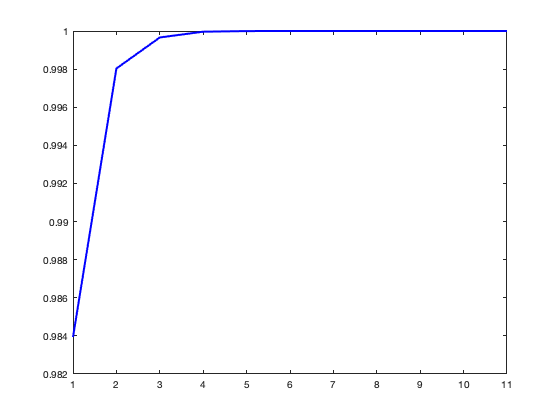


[u,s,v] = svd(A);

s = diag(s);

E = cumsum(s.^2)./sum(s.^2);

plot(E,'-b','LineWidth',2)


Bn = zeros(size(B));

for i=1:4
    Bn = Bn + ( (u(:,i)'*f)/s(i) )*v(:,i);
end

disp(Bn)

    0.3914
    0.2898
    0.2242
    0.1693
    0.1135
    0.0518
   -0.0162
   -0.0837
   -0.1291
   -0.1016
    0.1060



# Problem 4

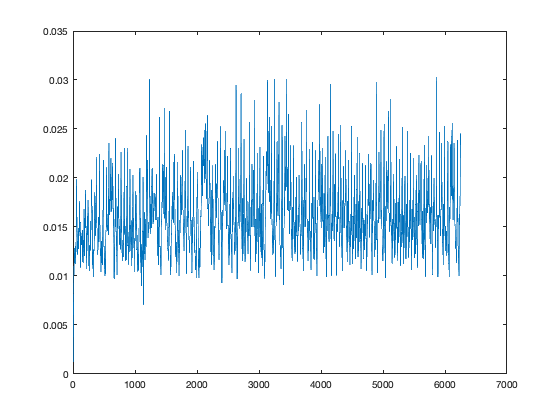

clearvars; clc;

tic

load ExamData.mat

plot(gradient(t)) %check time steps 

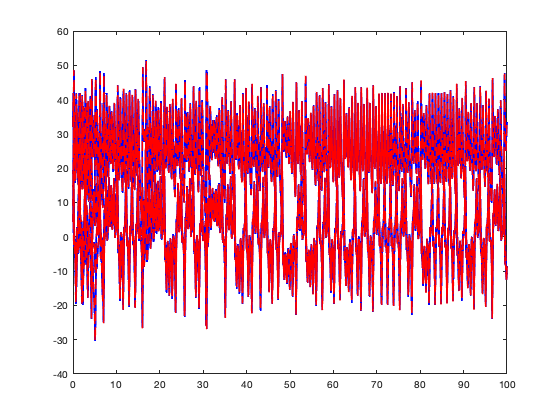

% You see that it is not equally spaced data.
% However, since there are no big spikes, there are no missing measurements.
% We can use interpolation to fix this.

tn = linspace(min(t),max(t),20000)'; %create equally spaced time vector
                                     %and increase number of measurements.
                                     
Xn =zeros(length(tn), size(X,2)); %initialize matrix to store interpolated data


for i=1:size(X,2)
    Xn(:,i) = interp1(t,X(:,i),tn,"spline");
end

%Check the interpolation
plot(t,X,'-b','LineWidth',2);
hold on
plot(tn,Xn,'--r','LineWidth',1.5)

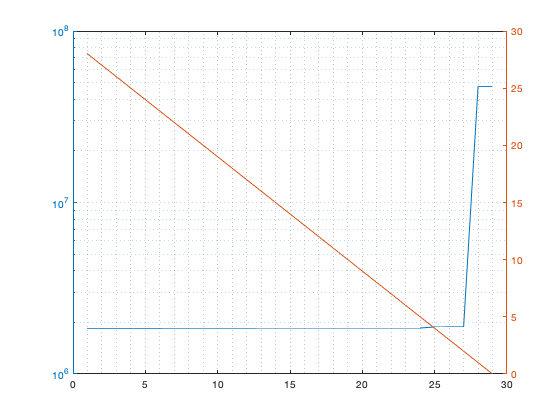

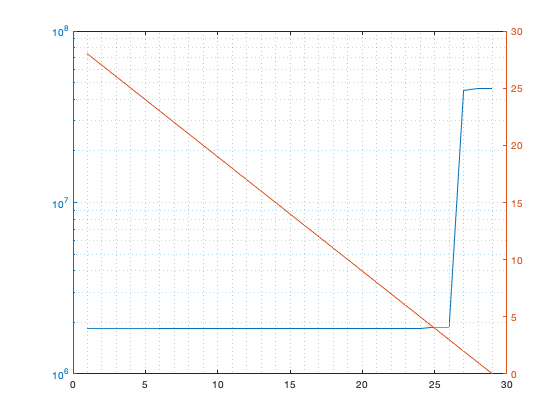

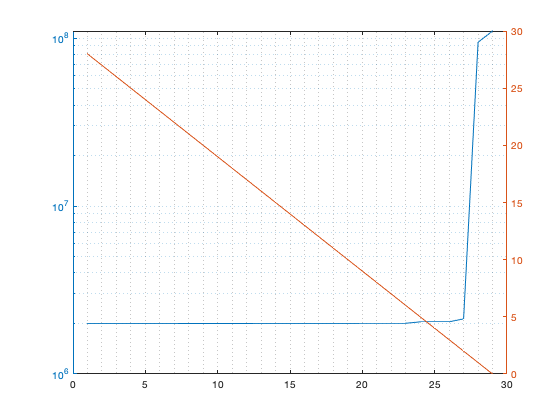

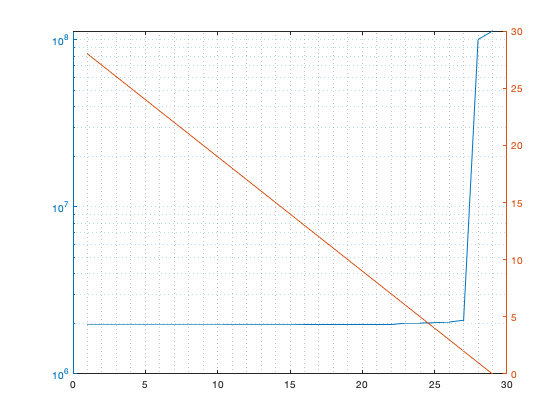

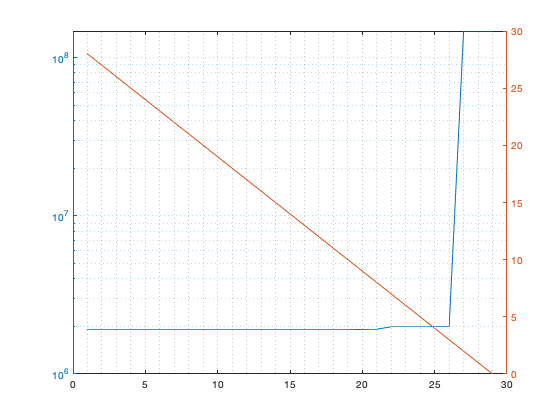

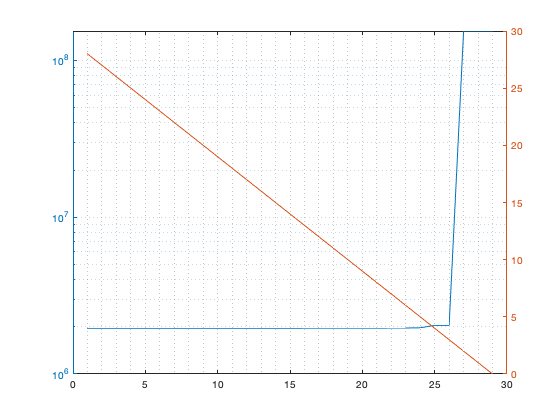



%Now we prepare for solving the inverse problem
tau = tn(2)-tn(1); %Step size
Xdot = (Xn(2:end,:)-Xn(1:end-1,:))./tau;
Xn(end,:) = [];
tn(end) = [];

%Create the expansion matrix
A = [ones(size(tn)), Xn]; %Now A has the constant term and the linear terms
TermName = {'const', 'x_1', 'x_2', 'x_3', 'x_4', 'x_5', 'x_6'};
N = size(Xn,2);

% We add the quadratic terms one by one
for i=1:N 
    for j=i:N 
        A = [A, (Xn(:,i).*Xn(:,j))];
        TermName = cat(2,TermName,['x_' num2str(i) 'x_' num2str(j)]);
    end
end


B0 = pinv(A)*Xdot;

B = zeros(size(B0));
for i=1:size(Xdot,2)   
    b = Hit(A,Xdot(:,i));
    
    
    L2 = sum((A*b-Xdot(:,i)).^2);
    L0  = sum(~~b);
    
    figure
%     subplot(6,1,i)
    yyaxis left
    semilogy(L2)
    
    yyaxis right
    plot(L0)
    
    grid minor
end

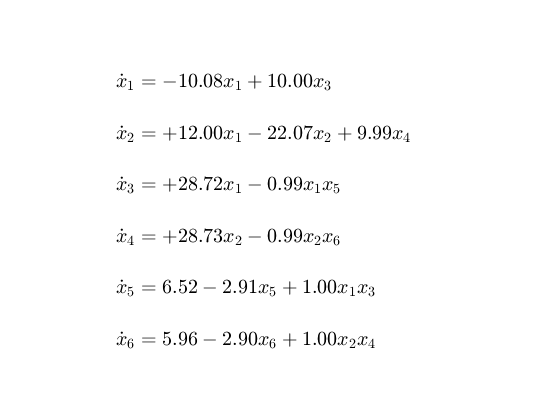

% From the figures above you see clearly that the best solutions have the
% following L0 respectively 

L0best = [2 3 2 2 3 3];

% L0best = [4 4 4 4 4 4];

%re-pick the best solutions
B = zeros(size(B0));
for i=1:size(Xdot,2)   
    b = Hit(A,Xdot(:,i));
    ix = find(sum(~~b)==L0best(i));
    B(:,i) = b(:,ix);
end

%get the ODE equations (we will round the parameters to two decimal places)

figure
for i=1:size(B,2)
    b = round(B(:,i),2);
    ix = find(b);
    eqn = ['$\dot{x}_' num2str(i) ' = '];
    for j=1:length(ix)
        if ix(j)==1
            eqn = cat(2,eqn, num2str(b(ix(j))));
        else
            eqn = cat(2,eqn, [num2str(b(ix(j)),'%+2.2f') TermName{ix(j)}]);
        end
        
    end
    eqn = cat(2, eqn, '$');
    
    text(0.1,1-0.15*i,eqn,'Interpreter',"latex",'FontSize',20)
end
set(gca,'FontSize',20)
box off
axis off

time = toc

time = 2.9928

function B = Hit(A,y)
x0 = pinv(A)*y;
N = size(A,2);
B = zeros(N,N+1);
IX = 1:N;
i = 1;
while ~isempty(IX)
 B(IX,i) = x0;
 [~,pos] = min(abs(x0));
 IX(pos) = [];
 x0 = pinv(A(:,IX))*y;
 i = i+1;
end
end